# Project1: Condition Monitoring of Ball Bearing using Hjorth's parameters

Handong Global University

School of Mechanical & Control Engineering

Industrial AI & Automation 24-2 

Team: HSN

Teammates: Yun-ki Noh 21800226, Si-on Seo 21800360, Ho-jin Jang 22100645

Date: 2024.10.22

## Wind Turbine High-Speed Bearing Prognosis Dataset

## 1. Introduction

    The fault of the bearing is the biggest cause of factory fault. When ball bearing faults happen, people have to stop factory system including ball bearing part. And as spending time to check which ball breaing was broken, people had to pay high cost from delay time of operating factory. In this reason, people tried to predict Remaining Useful Life(RUL) of ball bearing with many features from ball bearing's signal. 

    However, extracting many features and selecting specific features as a health indicator demand a lot of times. In this situation, to reduce consumming time for extracting & selecting features for health indicator, Detectivity can be used as a health indicator feature. From 'Detectivity: A combination of Hjorth’s parameters for condition monitoring of ball bearings.' of '*Mechanical Systems and Signal Processing', *detectivity can be calculated like this: [1]


$$\begin{array}{l}
\to y=\textrm{ball}\;\textrm{bearing}\;\textrm{signal}\;\textrm{data}\\
\to \;\textrm{Activity}=\sigma^{2\;} ,\;\textrm{Mobility}=√\frac{\textrm{Activity}\left(\textrm{diff}\left(y\right)\right)}{\textrm{Activity}\left(y\right)},\;\textrm{Complexity}=√\frac{\textrm{Mobility}\left(\textrm{diff}\left(y\right)\right)}{\textrm{Mobility}\left(y\right)}\\
\to {\;A}_{\textrm{ref}} =\textrm{mean}\left(\textrm{Activity}\right),{\;M}_{\textrm{ref}} =\textrm{mean}\left(\textrm{Mobility}\right),C_{\textrm{ref}} =\textrm{mean}\left(\textrm{Complexity}\right)\\
\to {\textrm{Act}}_{\left(\textrm{dB}\right)} =10*\log_{10} \left(\frac{\textrm{Act}}{{\textrm{Act}}_{\textrm{ref}} }\right),{\textrm{Mob}}_{\left(\textrm{dB}\right)} =10*\log_{10} \left(\frac{\textrm{Mob}}{{\textrm{Mob}}_{\textrm{ref}} }\right),{\textrm{Com}}_{\left(\textrm{dB}\right)} =10*\log_{10} \left(\frac{\textrm{Com}}{{\textrm{Com}}_{\textrm{ref}} }\right)\\
\to \textrm{Detectivity}={\textrm{Act}}_{\left(\textrm{dB}\right)} -{\textrm{Mob}}_{\left(\textrm{dB}\right)} +{\textrm{Com}}_{\left(\textrm{dB}\right)} 
\end{array}$$


    Hjorth’s parameters(Activity, Mobility, and Complexity) are indicator as time domain features.[1]. In commen case, these features have been used for analysis of electroencephalography signals. From these three parameters, we calculated new parameter, 'Detectivity'[1]. Detectivity is indicator for detecting ball bearing fault from bearing signal. From the 'Detectivity' journal, we would able to reduce the time spent extracting and selecting features by using Detectivity as a health indicator for RUL prediction. To comfirm this arguement, we planned to compare RUL prediction performance from Detectivity with traditional features. With WindTurbineProgonosis Dataset, we worked on the project like this:

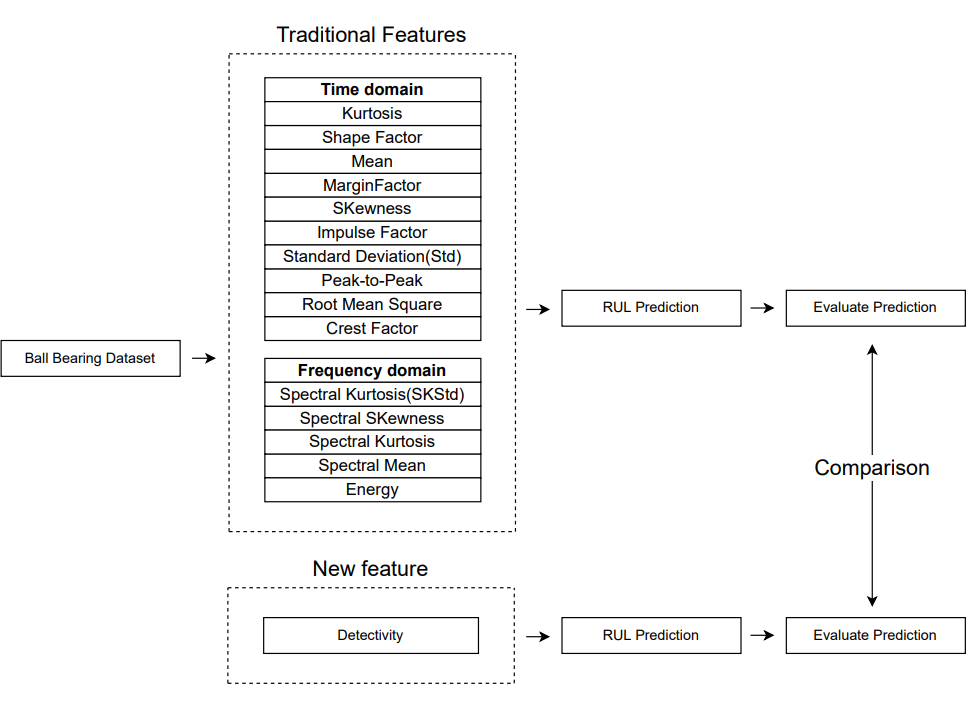

**Figure 1. Overall Structure of Our Project**

    In the Case 1, we used "MATLAB's Wind Turbine Bearinng Prognosis Tutorial" to prepare detectivity's RUL prediction performance. [Link: [풍력 터빈 고속 베어링 예지진단 - MATLAB & Simulink - MathWorks 한국](https://kr.mathworks.com/help/predmaint/ug/wind-turbine-high-speed-bearing-prognosis.html)]

## 2. Dataset

          - WindTurbineProgonosis Dataset:

- Hardware: 20-tooth pinion gea / 2MW 

- Sampling time: 6s per day

- Samplng period: 50 days

- Sampling frequency: 97656Hz

- Data number: 585,936 data of each 50 files

- link: [GitHub - mathworks/WindTurbineHighSpeedBearingPrognosis-Data: Data set for Wind Turbine High-Speed Bearing Prognosis example in Predictive Maintenance Toolbox](https://github.com/mathworks/WindTurbineHighSpeedBearingPrognosis-Data)

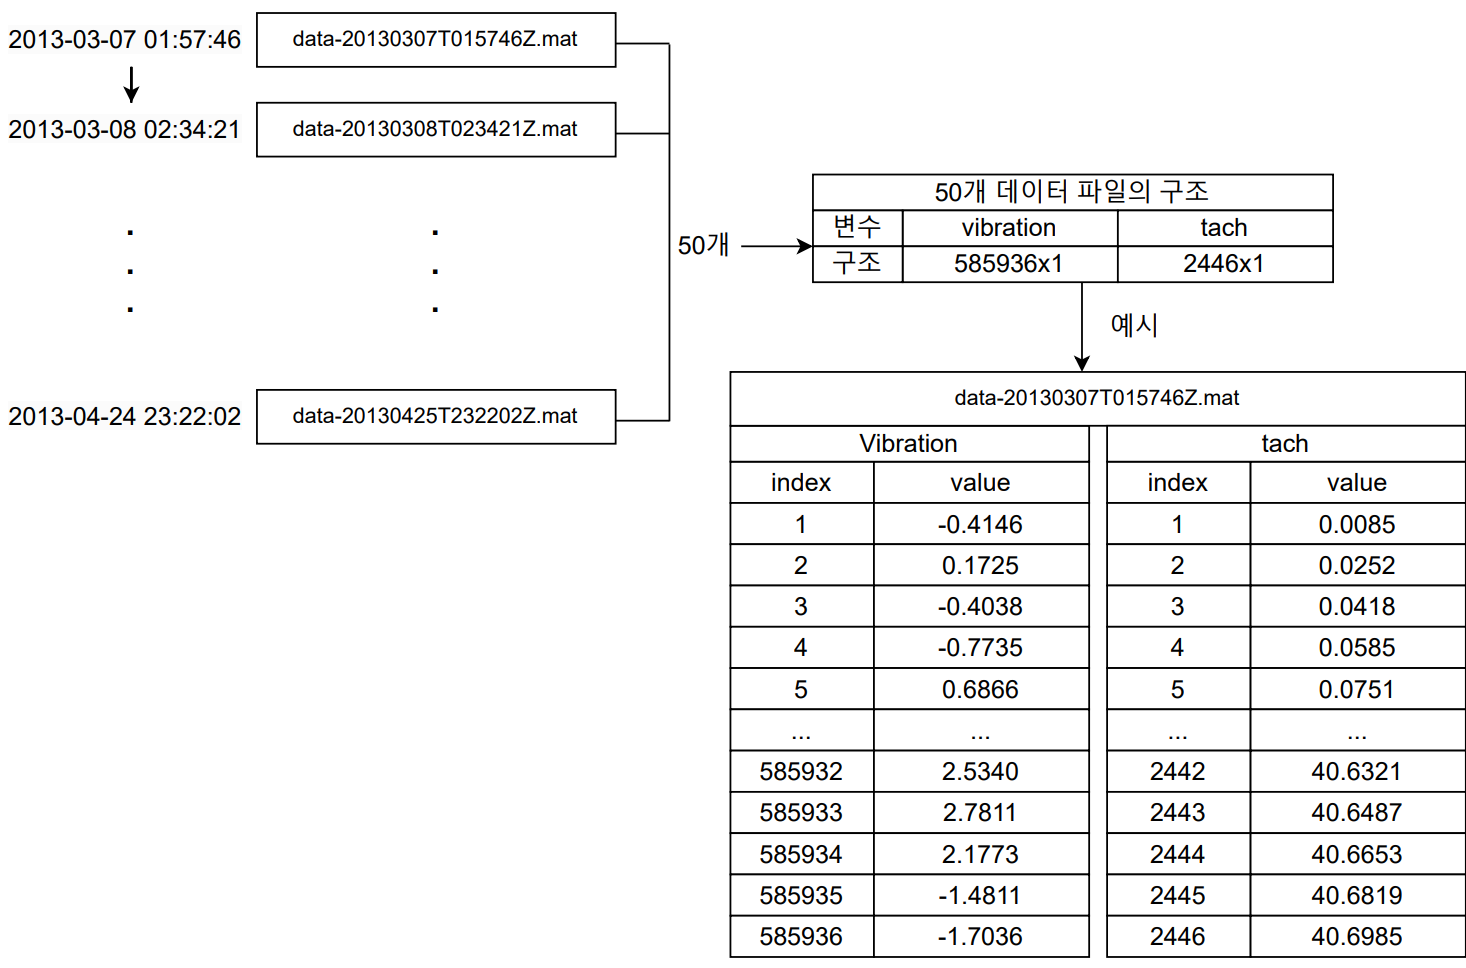

**Figure 2. Structure of WindTurbineProgonsis Dataset**

#### 2-1. Import Dataset

clear all; close all;

% Import WT dataset
hsbearing = fileEnsembleDatastore('Full-Data', '.mat');

timeUnit = 'day';

hsbearing.DataVariables = ["vibration", "tach", "SpectralKurtosis"];
hsbearing.IndependentVariables = "Date";
hsbearing.SelectedVariables = ["Date", "vibration", "tach"];
hsbearing.ReadFcn = @helperReadData;
hsbearing.WriteToMemberFcn = @helperWriteToHSBearing;
tall(hsbearing);  % Show Elements of Selected Variables. 

'helperReadData'은(는) Wind Turbine High-Speed Bearing Prognosis에 사용되었습니다.

오류 발생: predmaint.internal.pmdata.PMDatastore/read (196번 라인)
                    throw(E)

오류 발생: matlab.io.Datastore/previe

fs = 97656; % Hz

#### 2-2. Plot Raw Dataset  

    This dataset include wind turbine vibrations signal. To understand the whold trend of data, We plotted vibration data from 0 to 50 days.

% Vibration
% Reset hsbearing
reset(hsbearing);
tstart = 0;

% Create and center figure
figure('Units', 'normalized', 'Position', [0.3, 0.3, 0.4, 0.6]); % Center the figure

hold on;
while hasdata(hsbearing)
    data = read(hsbearing);

    v = data.vibration{1};
    t = tstart + (1:length(v)) / fs;
    plot(t(1:10:end), v(1:10:end));
    tstart = t(end);
end
hold off;

% Labeling and formatting the plot
xlabel('Time (s), 6 seconds per day, 50 days in total');
ylabel('Acceleration (g)');
title('Vibration Data Over Time');
grid on;
% Tach
% Reset hsbearing 
reset(hsbearing);
tstart = 0;

% Plot tachometer's dataset
figure;
hold on;
while hasdata(hsbearing)
    data = read(hsbearing);

    tach = data.tach{1};
    t = tstart + (1:length(tach))/fs;
    plot(t, tach);
    tstart = t(end);
end
hold off;
xlabel('Time (s), 6 seconds per day, 50 days in total');
ylabel('RPM');
title('Tachometer Data Over Time');
grid on;

#### 2-3. Exract Vibration, Tach, and Spectral Kurtosis Dataset 

    Extractin vibration, tach, and SpectralKurtosis for Detectivity and Traditional Features.

% Extract vibration, tach, and SpectralKurtosis
hsbearing.DataVariables = ["vibration","tach", "SpectralKurtosis"];
colors = parula(50);
reset(hsbearing)
day = 1;
vibration_data = zeros(585936,50);
tachometer_data = zeros(2446,50);
count = 1;

% Extract vibration data of 50 files
while hasdata(hsbearing)
    data = read(hsbearing);
    data2add = table;
    
    % Spectral Kurtosis
    wc = 128;
    [SK, F] = pkurtosis(v, fs, wc);
    data2add.SpectralKurtosis = {table(F, SK)};

    % Get the vibration signal
    v = data.vibration{1};
    vibration_data(:,count) = v;
    
    % Count untill 50 days
    day = day + 1;

    count = count+1;
end

### 3. Data Processing: Feature Extraction & Selection

#### 3-1. Extract Traditional Features

       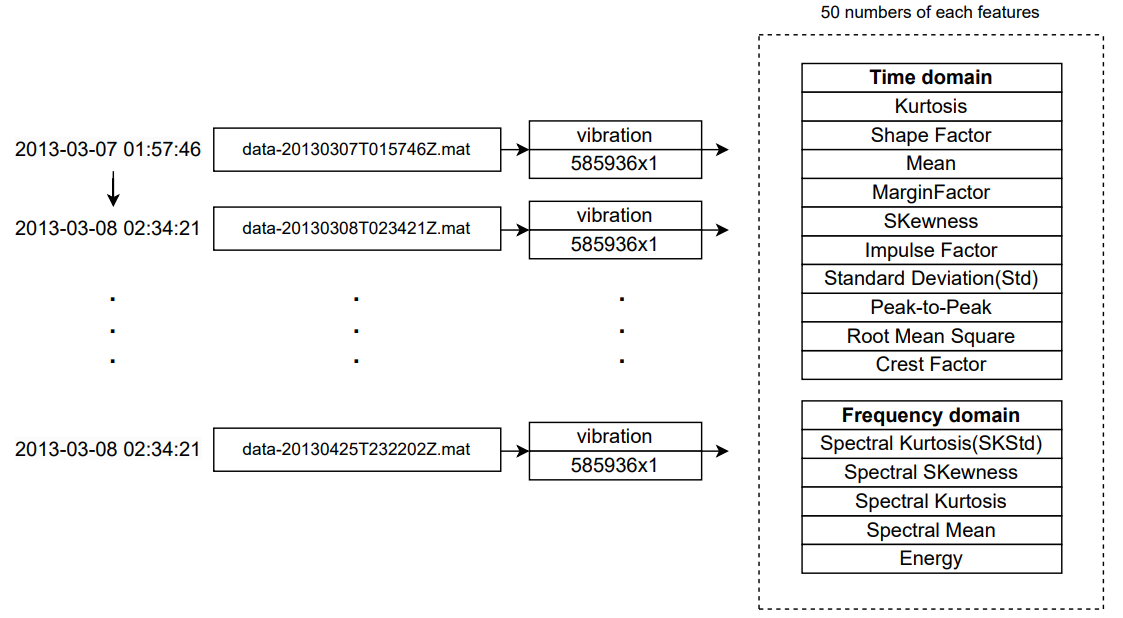                                            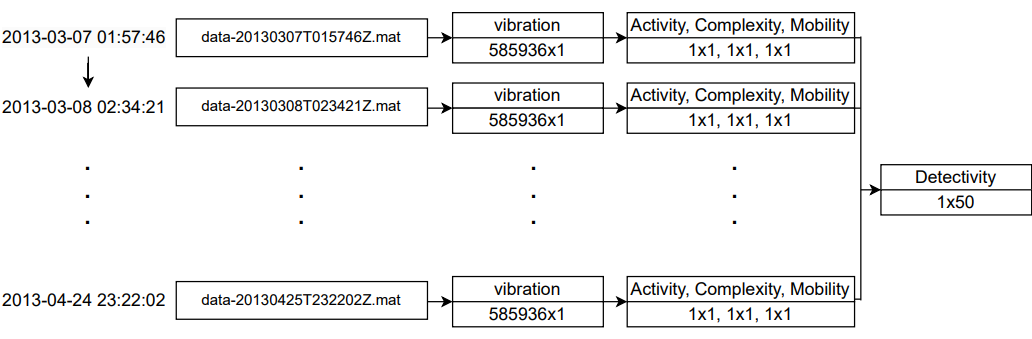

% Extract Traditional Features
hsbearing.DataVariables = [hsbearing.DataVariables; "Mean"; "Std"; "Skewness"; "Kurtosis"; "Peak2Peak"; ...
    "RMS"; "CrestFactor"; "ShapeFactor"; "ImpulseFactor"; "MarginFactor"; "Energy"; ...
    "SKMean"; "SKStd"; "SKSkewness"; "SKKurtosis"];

hsbearing.SelectedVariables = ["vibration", "SpectralKurtosis"];
reset(hsbearing)
while hasdata(hsbearing)
    data = read(hsbearing);
    v = data.vibration{1};
    SK = data.SpectralKurtosis{1}.SK;
    features = table;
    
    % Time Domain Features
    features.Mean = mean(v);
    features.Std = std(v);
    features.Skewness = skewness(v);
    features.Kurtosis = kurtosis(v);
    features.Peak2Peak = peak2peak(v);
    features.RMS = rms(v);
    features.CrestFactor = max(v)/features.RMS;
    features.ShapeFactor = features.RMS/mean(abs(v));
    features.ImpulseFactor = max(v)/mean(abs(v));
    features.MarginFactor = max(v)/mean(abs(v))^2;
    features.Energy = sum(v.^2);
    
    % Spectral Kurtosis related features
    features.SKMean = mean(SK);
    features.SKStd = std(SK);
    features.SKSkewness = skewness(SK);
    features.SKKurtosis = kurtosis(SK);
    
    % write the derived features to the corresponding file
    writeToLastMemberRead(hsbearing, features);
end

#### 3-2. Extract Detectivity

% Extract Detectivity
num_cycles = 50; 

% Initialize an array to store 50 four parameter values
activities = zeros(1, num_cycles);
mobilities = zeros(1, num_cycles);
complexities = zeros(1, num_cycles);
detectivitiy = zeros(1, num_cycles);

% Repeat 50 times to extract detectivity
for cycle_index = 1:num_cycles
    if ~hasdata(hsbearing)
        reset(hsbearing); % If no more data, reset to read again
    end
    
    features = table;
    
    % Extract 50 numbers of activity, mobility, and complexity
    for j = 1:num_cycles
        % Calculate activity
        v = vibration_data(:,j);
        activities(j) = var(v);

        % Calculate mobility
        first_derivative = diff(v);
        mobilities(j) = sqrt(var(first_derivative) / activities(j));

        % Calculate complexity
        second_derivative = diff(first_derivative);
        complexities(j) = sqrt(var(second_derivative) / var(first_derivative))/sqrt(var(first_derivative) / var(v));
    end

    % Reference values
    A_ref = mean(activities);
    M_ref = mean(mobilities);
    C_ref = mean(complexities);

    % Calculate dB values of each three parameters
    activity_j_dB = 10 * log10(activities / A_ref);
    mobility_j_dB = 10 * log10(mobilities / M_ref);
    complexity_j_dB = 10 * log10(complexities / C_ref);
    
    % Calculate detectivity
    detectivity = activity_j_dB - mobility_j_dB + complexity_j_dB;
end

hsbearing.DataVariables = [hsbearing.DataVariables; "detectivity"];

% Store all 50 detectivity values in the features table
features.detectivity = detectivity;

#### 3-3. Combine Whole Dataset as a Timetable

% Select the derived features for further processing or inspection
hsbearing.SelectedVariables = ["Date", "Mean", "Std", "Skewness", "Kurtosis", "Peak2Peak", ...
    "RMS", "CrestFactor", "ShapeFactor", "ImpulseFactor", "MarginFactor", "Energy", ...
    "SKMean", "SKStd", "SKSkewness", "SKKurtosis"];

featureTable = gather(tall(hsbearing));
% detectivity 값을 1x50 테이블로 변환하여 추가
detectivityTable = array2table(features.detectivity', 'VariableNames', {'Detectivity'});

% Date 열을 기준으로 featureTable과 detectivityTable을 결합
featureTable = [featureTable, detectivityTable];


featureTable = table2timetable(featureTable)

#### 3-4. Plot Detectivity

    Detectivity shows upward trend. But, there are many fluctuation of going up and down. This fluctuation would make bad prediction performance, because smooth trend of feature is necessary to get exact prediction.

variableNames = featureTable.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), featureTable);
featureTableSmooth.Properties.VariableNames = variableNames;
featureTableSmooth = featureTableSmooth(1:end, :);

% Plot the calculated detectivity values
figure;
plot(featureTable.Detectivity, '-o');
title('Detectivity Plot');
xlabel('Sample Number');
ylabel('Detectivity (dB)');
grid on;

    To make detectivity more smoothly, we applied smooth filter to detectivity signal.

variableNames = featureTable.Properties.VariableNames;
featureTableSmooth = varfun(@(x) movmean(x, [5 0]), featureTable);
featureTableSmooth.Properties.VariableNames = variableNames;
figure
hold on
plot(featureTable.Date, featureTable.Detectivity)
plot(featureTableSmooth.Date, featureTableSmooth.Detectivity)
hold off
xlabel('Time')
ylabel('Feature Value')
legend('Before smoothing', 'After smoothing')
title('Detectivity')   

#### 3-5. Plot Traditional Features

% 변수 이름 저장
variableNames = featureTable.Properties.VariableNames;

% 각 피처에 대해 이동 평균을 적용하여 새로운 테이블 생성
featureTableSmooth = featureTable;  % 원본 테이블 복사
featureTableSmooth.Kurtosis = movmean(featureTable.Kurtosis, [5 0]);
featureTableSmooth.ShapeFactor = movmean(featureTable.ShapeFactor, [5 0]);
featureTableSmooth.Mean = movmean(featureTable.Mean, [5 0]);
featureTableSmooth.MarginFactor = movmean(featureTable.MarginFactor, [5 0]);
featureTableSmooth.SKStd = movmean(featureTable.SKStd, [5 0]);

% 그래프 그리기
features = {'Kurtosis', 'ShapeFactor', 'Mean', 'MarginFactor', 'SKStd'};
for i = 1:length(features)
    figure;
    hold on;
    plot(featureTable.Date, featureTable.(features{i}), 'DisplayName', 'Before smoothing');
    plot(featureTableSmooth.Date, featureTableSmooth.(features{i}), 'DisplayName', 'After smoothing');
    hold off;
    xlabel('Time');
    ylabel(features{i});
    legend('Before smoothing', 'After smoothing');
    title(features{i});
end

#### 3-6. Select Traditional Features

   After applying smoothing fiter,we calculated monotonicity to select health indicator features. We set threshold of monotonicity value as 0.3: Kurtosis, ShapeFactor, Mean, MarginFactor, and SKStd are over 0.3. 

% featureTable을 일반 테이블로 변환
featureTableNoDetectivity = removevars(featureTableSmooth, 'Detectivity');
featureImportance = monotonicity(featureTableNoDetectivity, 'WindowSize', 0);
helperSortedBarPlot(featureImportance, 'Monotonicity');
featureSelected = featureTableSmooth(:, featureImportance{:,:}>0.3)
meanTrain = mean(featureSelected{:,:});
sdTrain = std(featureSelected{:,:});
featureDataNormalized = (featureSelected{:,:} - meanTrain)./sdTrain;
coef = pca(featureDataNormalized);

PCA1 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 1);
PCA2 = (featureSelected{:,:} - meanTrain) ./ sdTrain * coef(:, 2);

% PCA1 그래프 그리기
figure;
plot(PCA1, 'b-o');
xlabel('Sample Index');
ylabel('PCA1');
title('PCA1 Plot');
grid on;
% PCA2 그래프 그리기
figure;
plot(PCA2, 'b-o');
xlabel('Sample Index');
ylabel('PCA2');
title('PCA2 Plot');
grid on;
% Select PCA1 as a healthindicator of Traditional Features
healthIndicator_pca1 = PCA1;

### 4. RUL Prediction & Evaluation

#### 4-1. Build Model

    Now, we got two tpyes of health indicator features: detectivity, and PCA. To train RUL prediction model with these features, we divided dataset into 2:5, train dataset:test dataset. In this chapter, we dealt with only detectivity code, and used pre-extracted Traditional features' result.

% Divide Detectivity dataset into train and test.
breaktime = datetime(2013, 3, 27);
breakpoint = find(featureTableSmooth.Date < breaktime, 1, 'last');
healthIndicator_detectivity = featureTableSmooth.Detectivity;

    To predcit RUL, we used fitting model: Exponential degradation mode(EDM). [3]


$$h\left(t\right)=\phi +\theta \;\exp \left(\beta \;t+\epsilon \;-\frac{\sigma^2 }{2}\right)$$


    EDM shows the degradation level of system by using the upwarding fitting graph. $\theta$ and $\beta$ are charge of the  volatility of model. $\phi$ and $\epsilon$ mean the axis position of fitting model and $\sigma^2$ contains gaussian noise. Every trainning of fitting, this model find the optimum value to predict true RUL.

% healthIndicator of detectivity
healthIndicator_detectivity = healthIndicator_detectivity - healthIndicator_detectivity(1);
healthIndicator_pca1 = healthIndicator_pca1 - healthIndicator_pca1(1);

% Threshold for failure
threshold_detectivity = healthIndicator_detectivity(end);
threshold_pca1 = healthIndicator_pca1(end);

% Fitting model
% 모델 파라미터 조정
mdl_detectivity = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold_detectivity/(threshold_detectivity + 1))^2, ...
    'SlopeDetectionLevel', 0.05);


mdl_pca1 = exponentialDegradationModel(...
    'Theta', 1, ...
    'ThetaVariance', 1e6, ...
    'Beta', 1, ...
    'BetaVariance', 1e6, ...
    'Phi', -1, ...
    'NoiseVariance', (0.1*threshold_pca1/(threshold_pca1 + 1))^2, ...
    'SlopeDetectionLevel', 0.05);

#### 4-2. Predict RUL

    By using matlab function [3], we predicted RUL and evaluated the prediction results.

% Detectivity
totalDay_detectivity = length(healthIndicator_detectivity) - 1;
estRULs_detectivity = zeros(totalDay_detectivity, 1);
trueRULs_detectivity = zeros(totalDay_detectivity, 1);
CIRULs_detectivity = zeros(totalDay_detectivity, 2);
pdfRULs_detectivity = cell(totalDay_detectivity, 1);

% pca1
totalDay_pca1 = length(healthIndicator_pca1) - 1;
estRULs_pca1 = zeros(totalDay_pca1, 1);
trueRULs_pca1 = zeros(totalDay_pca1, 1);
CIRULs_pca1 = zeros(totalDay_pca1, 2);
pdfRULs_pca1 = cell(totalDay_pca1, 1);

% RUL Prediction with Detectivity
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);
for currentDay = 1:totalDay_detectivity

    % Update model parameter posterior distribution
    update(mdl_detectivity, [currentDay healthIndicator_detectivity(currentDay,:)])

    % Predict Remaining Useful Life
    [estRUL_detectivity, CIRUL_detectivity, pdfRUL_detectivity] = predictRUL(mdl_detectivity, ...
                                         [currentDay healthIndicator_detectivity(currentDay)], ...
                                         threshold_detectivity);
    trueRUL_detectivity = totalDay_detectivity - currentDay + 1;

    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator_detectivity, mdl_detectivity, threshold_detectivity, timeUnit);
    helperPlotRUL(ax2, trueRUL_detectivity, estRUL_detectivity, CIRUL_detectivity, pdfRUL_detectivity, timeUnit)

    % Keep prediction results
    estRULs_detectivity(currentDay) = estRUL_detectivity;
    trueRULs_detectivity(currentDay) = trueRUL_detectivity;
    CIRULs_detectivity(currentDay, :) = CIRUL_detectivity;
    pdfRULs_detectivity{currentDay} = pdfRUL_detectivity;

    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

% RUL Prediction with PCA1
figure
ax1 = subplot(2, 1, 1);
ax2 = subplot(2, 1, 2);
for currentDay = 1:totalDay_pca1

    % Update model parameter posterior distribution
    update(mdl_pca1, [currentDay healthIndicator_pca1(currentDay,:)])

    % Predict Remaining Useful Life
    [estRUL_pca1, CIRUL_pca1, pdfRUL_pca1] = predictRUL(mdl_pca1, ...
                                         [currentDay healthIndicator_pca1(currentDay)], ...
                                         threshold_pca1);
    trueRUL_pca1 = totalDay_pca1 - currentDay + 1;

    % Updating RUL distribution plot
    helperPlotTrend(ax1, currentDay, healthIndicator_pca1, mdl_pca1, threshold_pca1, timeUnit);
    helperPlotRUL(ax2, trueRUL_pca1, estRUL_pca1, CIRUL_pca1, pdfRUL_pca1, timeUnit)

    % Keep prediction results
    estRULs_pca1(currentDay) = estRUL_pca1;
    trueRULs_pca1(currentDay) = trueRUL_pca1;
    CIRULs_pca1(currentDay, :) = CIRUL_pca1;
    pdfRULs_pca1{currentDay} = pdfRUL_pca1;

    % Pause 0.1 seconds to make the animation visible
    pause(0.1)
end

    **Figure 12. RUL Prediction Results: Left is from Detectivity, Right is from Ohter Features **[3]

#### 4-3. RUL Evaluation

    $\alpha$-$\lambda$ plot is visual RUL diagnosis for prediction evaluation. Blue line is true RUL, and the blue area around the true RUL is the allowable range of change(20% possibility of discorrect). Red lines are predicted RUL after detecting degradation. The red area around the prediction RUL is allowable range of change(20% possibility of discorrect). By checking the shared area between true and prediction, we can know that when this model predict correct RUL.

    As broad as possibile between true and predction RUL area, the model can be determined as high performance of RUL prediction model. When comapring with fitting model from detectivity and from Traditional features, it seems that two types of model show similar performance. However, we can compare performance of RUL prediction by chekcing the probability of RUL. 

alpha = 0.2;
detectTime_detectivity = mdl_detectivity.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs_detectivity, estRULs_detectivity, CIRULs_detectivity, ...
    pdfRULs_detectivity, detectTime_detectivity, breakpoint, timeUnit);
title('\alpha-\lambda Plot')

    **Figure 13. **$\alpha$**-**$\lambda$** plot, Left is from Detectivity, Right is from Ohter Features **[2]

We extract probability of two cases: Detectivity and Traditional Features.

figure
t = 1:totalDay_detectivity;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

alpha = 0.2;
detectTime_pca1 = mdl_pca1.SlopeDetectionInstant;
prob = helperAlphaLambdaPlot(alpha, trueRULs_pca1, estRULs_pca1, CIRULs_pca1, ...
    pdfRULs_pca1, detectTime_pca1, breakpoint, timeUnit);
title('\alpha-\lambda Plot')
figure
t = 1:totalDay_pca1;
hold on
plot(t, prob)
plot([breakpoint breakpoint], [0 1], 'k-.')
hold off
xlabel(['Time (' timeUnit ')'])
ylabel('Probability')
legend('Probability of predicted RUL within \alpha bound', 'Train-Test Breakpoint')
title(['Probability within \alpha bound, \alpha = ' num2str(alpha*100) '%'])

    Probability graphs show different performance results of two methods. The first graph is from detectivity's RUL prediction. According to this graph, detectivity could not predict date of breakpoint. In contrast of this, probabilites of RUL prediction from Traditional features predict well date of breakpoint. In addition to this, as closing to the end of date, detectivity became not able to predict RUL.

    This result show us that detectivity could not work better than Traditional features as a RUL prediction material. This low quality of RUL predction may occure from high volatility of detectivity. Although PCA from Traditional features was increased relatively steadily, detectivity was a lot of fluctuation. This unstability would have caused a relatively low performance prepared with Traditional features.

    However, the simple method of extracting detectivity from raw data can be a strong point compared with method of using Traditional features. Although detectivity did not show good performance in this case1, we could check the possibility of detectivity as a feature for RUL prediction.

## 5. Conclusion

    We tried to predict RUL by using machine learning with WindTurbineProgonosis Dataset. Because traditional method of extracting & selecting features takes a long time, we planned to use Detectivity as a health indicator. And to comfirm Detectivity's  availability as a health indicator for RUL prediction, we compared Detectivity's RUL prediction performance with traditional features's performance. 

    The criteria of evaluating RUL prediction performance was that how much the predicted RUL and real RUL were sharing same area. As date becomes to be closed to 0 days of RUL, probability of both method showed low accuracy of RUL prediction. However, RUL prediction of Detectivity showed almost zero probability. In addition to this, at the fault date, Detectivity could not predict ball bearing fault. These results mean Detectivity can not work as health indicator for RUL prediction.

   We concluded that using Detectivity would not guarantee high performance of RUL prediction. We thought that this low performance was happened from the limitation of machine learning. Although Detectivity showed the upward trend of ball bearing signal, because flucuation of Detectivity graph caused non-linearity, Detectivity could not show high accuracy of RUL prediction with machin learning. In this reason, we proposed to use deep learning model as a RUL prediction model. With deep learning model, we would able to overcome curve fitting model's limitation for non-linearity.

## References

[1] Cocconcelli, M., Strozzi, M., Camargo Molano, J. C., & Rubini, R. (2022). Detectivity: A combination of Hjorth’s parameters for condition monitoring of ball bearings. *Mechanical Systems and Signal Processing, 164*, 108247. [https://doi.org/10.1016/j.ymssp.2021.108247](https://doi.org/10.1016/j.ymssp.2021.108247)

[2] Saxena, A., Celaya, J., Balaban, E., Goebel, K., Saha, B., Saha, S., & Schwabacher, M. (2008). Metrics for evaluating performance of prognostic techniques. 2008 International Conference on Prognostics and Health Management (PHM), 1-8. [https://doi.org/10.1109/PHM.2008.4711436](https://doi.org/10.1109/PHM.2008.4711436)

[3] MathWorks. (n.d.). Wind Turbine High-Speed Bearing Prognosis. MathWorks. Retrieved October 28, 2024, from https://kr.mathworks.com/help/predmaint/ug/wind-turbine-high-speed-bearing-prognosis.html